Să se studieze teoretic și experimental condiționarea problemei determinării rădăcinilor ecuației polinomiale $x^n + a_1*x^{n-1} + a_2*x^{n-2} + ... + a_n = 0$ cunoscându-se coeficienții.

Se vor extrage numerele de condiționare pentru fiecare rădăcină a polinomului și se va studia grafic efectul perturbării fiecărui coeficient cu o variabilă aleatore care respectă legea normală/uniformă.

1. $(x-1)*(x-2)*...*(x-n) = 0 \Rightarrow roots = [1, 2, ..., n]$

2. $a_k = 2^{-k}$

Să se testeze pentru n = 20.

format compact;
n = 20;

mean = 0;
sigma = 1e-10;

lower_bound_unif = 1e-11;
upper_bound_unif = 1e-10;

% (x-1)(x-2) ... (x-n) = 0
roots_poly1 = 1:n;
poly1 = poly(roots_poly1);

% x^n + a_1 * x^(n-1) + ... + a^n = 0, a_n = 2^(-n)
poly2 = [1, 2 .^ -(1:n)]

poly2 =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


nc1 = root_cn(poly1, roots_poly1)

nc1 = 	1.0e+-36 *

    0.1609    0.1390    0.1088    0.0770    0.0493    0.0284    0.0147    0.0068    0.0028    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


figure(1);
hold on;
grid on;

scatter(roots_poly1, zeros(1, n), 100, 'filled', 'r', 'o', 'DisplayName', 'P1 (no perturbation)');
% ### DISTRIBUTIE NORMALA
norm_poly1 = poly1 + normrnd(mean, sigma, 1, n + 1);
try
    norm_poly1_roots = roots(norm_poly1)'
    scatter(real(norm_poly1_roots), imag(norm_poly1_roots), 25, 'filled', 'b', 'o', 'DisplayName', 'P1 (norm perturbation)');
catch e
    fprintf("Perturbare normala a intampinat o eroare: %s\n", e.message);
end

norm_poly1_roots =   20.0707 + 0.0000i  18.7275 - 0.5548i  18.7275 + 0.5548i  16.5632 - 1.0573i  16.5632 + 1.0573i  14.3376 - 0.8878i  14.3376 + 0.8878i  12.3630 - 0.2737i  12.3630 + 0.2737i  10.9316 + 0.0000i  10.0187 + 0.0000i   8.9958 + 0.0000i   8.0009 + 0.0000i   6.9999 + 0.0000i   6.0000 + 0.0000i   5.0000 + 0.0000i   4.0000 + 0.0000i   3.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


% ### DISTRIBUTIE UNIFORMA
unif_poly1 = poly1 + unifrnd(lower_bound_unif, upper_bound_unif, 1, n + 1);
try
    unif_poly1_roots = roots(unif_poly1)'
    scatter(real(unif_poly1_roots), imag(unif_poly1_roots), 25, 'filled', 'g', 'o', 'DisplayName', 'P1 (unif perturbation)');
catch e
    fprintf("Perturbare uniforma a intampinat o eroare: %s\n", e.message);
end

unif_poly1_roots =   19.9224 + 0.0000i  19.3125 + 0.0000i  17.6678 - 0.7987i  17.6678 + 0.7987i  15.4302 - 0.9415i  15.4302 + 0.9415i  13.3321 - 0.4974i  13.3321 + 0.4974i  11.8868 + 0.0000i  11.0166 + 0.0000i  10.0030 + 0.0000i   8.9980 + 0.0000i   8.0006 + 0.0000i   6.9999 + 0.0000i   6.0000 + 0.0000i   5.0000 + 0.0000i   4.0000 + 0.0000i   3.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


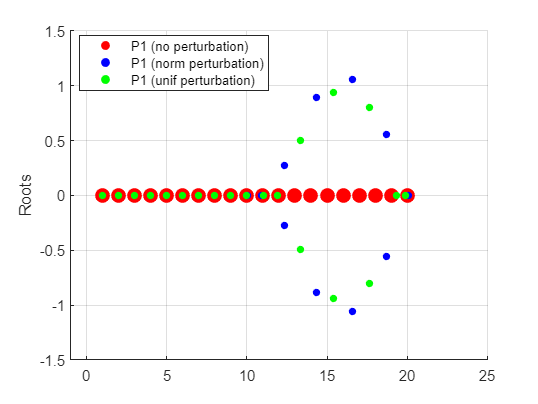

legend('Location','best')
ylabel('Roots');
xlim([-1, 25]);
ylim([-1.5, 1.5]);
hold off;

Se poate observa din plot ca in intervalul **[13, 19]**, chiar daca numerele de conditionare ale radacinilor sunt in termen de **10^-36**, perturbatiile mici aplicate produc rezultate diferite, in **plan complex**.Chiar si asa, perechile in acest interval sunt **perechi de numere complexe conjugate**, prezentand o simetrie. Rezultatul este contra-intuitiv avand in vedere magnitudinea rezultatului.

figure(2);
hold on;
grid on;

roots_poly2 = roots(poly2)';
nc2 = root_cn(poly2, roots_poly2)

nc2 = 	1.0e+09 *

    0.7804    0.7804    1.5433    1.5433    2.2717    2.2717    5.2211    5.2211    5.1045    5.1045    4.8738    4.8738    2.9494    2.9494    4.5343    4.5343    3.5612    3.5612    4.0935    4.0935


scatter(real(roots_poly2), imag(roots_poly2), 100, 'filled', 'r', 'DisplayName', 'P2 (no perturbation)');
% ### DISTRIBUTIE NORMALA
norm_poly2 = poly2 + normrnd(mean, sigma, 1, n+1);
try
    norm_poly2_roots = roots(norm_poly2)'
    scatter(real(norm_poly2_roots), imag(norm_poly2_roots), 25, 'filled', 'b', 'DisplayName', 'P2 (norm perturbation)');
catch e
    fprintf("Perturbare normala a intampinat o eroare: %s\n", e.message);
end

norm_poly2_roots =   -0.4944 - 0.0745i  -0.4944 + 0.0745i  -0.4505 - 0.2169i  -0.4505 + 0.2169i  -0.3665 - 0.3401i  -0.3665 + 0.3401i   0.4778 - 0.1474i   0.4778 + 0.1474i   0.4131 - 0.2817i   0.4131 + 0.2817i   0.3117 - 0.3909i   0.3117 + 0.3909i   0.1827 - 0.4654i   0.1827 + 0.4654i  -0.2500 - 0.4330i  -0.2500 + 0.4330i   0.0374 - 0.4986i   0.0374 + 0.4986i  -0.1113 - 0.4875i  -0.1113 + 0.4875i


% ### DISTRIBUTIE UNIFORMA
unif_poly2 = poly2 + unifrnd(lower_bound_unif, upper_bound_unif, 1, n+1);
try
    unif_poly2_roots = roots(unif_poly2)'
    scatter(real(unif_poly2_roots), imag(unif_poly2_roots), 25, 'filled', 'g', 'DisplayName', 'P2 (unif perturbation)');
catch e
    fprintf("Perturbare uniforma a intampinat o eroare: %s\n", e.message);
end

unif_poly2_roots =    0.4778 - 0.1474i   0.4778 + 0.1474i   0.4131 - 0.2817i   0.4131 + 0.2817i   0.3117 - 0.3909i   0.3117 + 0.3909i  -0.4944 - 0.0745i  -0.4944 + 0.0745i  -0.4505 - 0.2169i  -0.4505 + 0.2169i  -0.3665 - 0.3401i  -0.3665 + 0.3401i   0.1827 - 0.4654i   0.1827 + 0.4654i  -0.2500 - 0.4330i  -0.2500 + 0.4330i   0.0374 - 0.4986i   0.0374 + 0.4986i  -0.1113 - 0.4875i  -0.1113 + 0.4875i


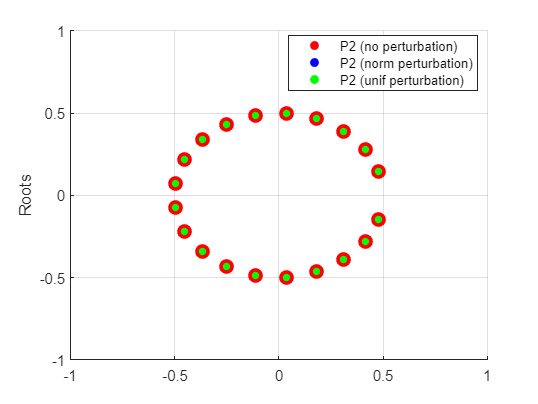

legend('Location','best')

xlim([-1, 1]);
ylim([-1, 1]);
ylabel('Roots');

hold off;

Se poate observa ca **radacinile **formeaza o **elipsa **in planul complex, sugerand faptul ca polinomal are o structura simetrica. Radacinile sunt in **perechi complexe conjugate**, iar perturbatiile aplicate schimba valorile radacinilor, insa cu o **valoare foarte mica**. Daca am aplica o perturbatie cu termeni mai mari, nu de ordinul ~10^-10, rezultatele ar fi mai departate de realitate, avand in vedere numerele de conditionare ale radacinilor fiind in termen de 10^9.